# Computational Methods in Physics (PHY4605) - **Logic and Conditional Statements**

## Overview

A **boolean** is a **logical data type** that can have only two values: `true` or `false`. Boolean values are often used to represent the outcome of comparisons or logical operations, such as equal, greater than, and, or, not, etc. We need boolean values for **conditional statements** because they allow us to **control the flow of our program based on certain conditions**. For example, if we want to execute a block of code only when a variable `x` is positive, we can use an if statement with a boolean expression `x > 0`. If this expression evaluates to `true`, the code inside the if block will run; otherwise, it will be skipped. Boolean values are essential for making **decisions and branching** in our code.

## Logic

MATLAB represents boolean data using the logical data type. This data type represents `true` and `false` states using the numbers `1` and `0`, respectively. Certain MATLAB functions and operators return logical values to indicate fulfillment of a condition. These logical values can be used to index into an array or execute conditional statements.

### Logical Operators

 From the following logical expressions:

2 > 0 
-1 > 0

MATLAB gives a value of `1` to a logical expression that is `true` and `0` to one that is `false`. Logical expressions can be constructed from the six relational operators as well as three logical operators shown below:

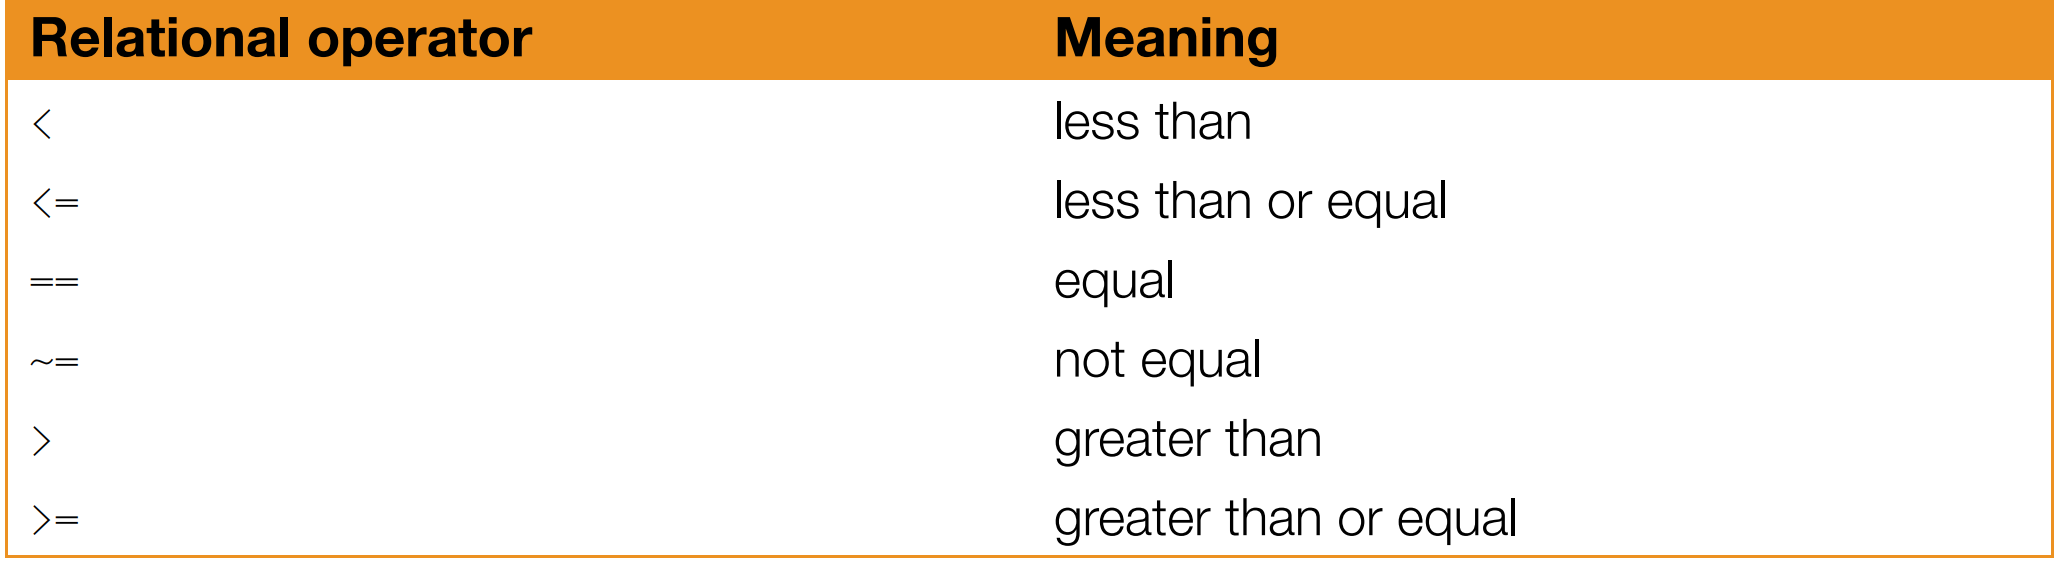

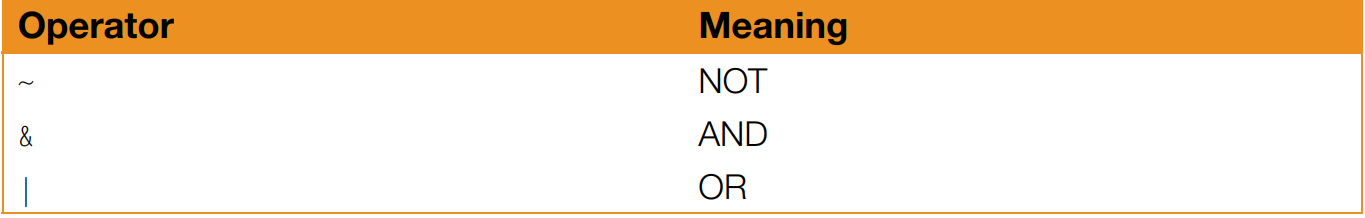

The table below shows the effects of these operators on the general logical expressions `lex1` and `lex2`. The `OR` operator (`|`) is technically an inclusive `OR`, because it is `true` when either or both of its operands are `true`. MATLAB also has an exclusive `OR` function `xor(a, b)` which is `1` (`true`) only when either but not both of `a` and `b` is `1`.

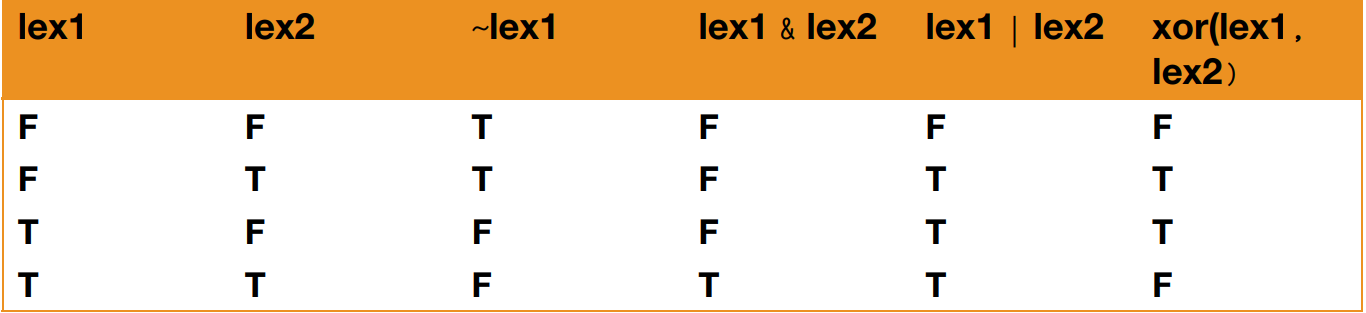

 Precedences may be overridden with brackets, e.g.:

~ 0 & 0 

returns `0` (`false`).

Whereas:

~ (0 & 0)

returns `1` (`true`). 

Some more examples:

a = true;
b = 4;
c = false;
x = 65;

(b * (b == 4) * a) & (a ~= 0) & ~c
(x >= 60) & (x < 70)
(a ~= 0) | (b ~= 0) | (c == 0)
~((a == 0) & (b == 0) & (c == 0)) 

### Logical Vectors

The logical operators can also operate on vectors (of the same size), returning logical vectors, e.g.:

logical([1 2 0 -4 0])

replaces all the non-zeros by `1`’s, and leaves the `0`’s untouched.

More examples:

a = [-1 0 3];
b = [0 3 1];

~ a 
a & b 
a | b 
xor(a, b)
a > 0 & b > 0
a > 0 | b > 0
~ a > 0
a + (~ b)
a > ~b
~ a > b

ans = 1×3 logical array
   0   1   0


~ (a > b)

ans = 1×3 logical array
   0   0   1


Notice the outputs of:

x = [-2 0 1 5 9];

ans = 1×3 logical array
   1   1   1


x(x >= 0 & x <= 6) 

ans = 1×3 logical array
   1   1   0


ans = 1×3 logical array
   0   0   1


x([5 1 3])

ans = 1×3 logical array
   0   1   1


v = logical([0 1 0 1 0])

ans = 1×3 logical array
   0   1   0


x(v)

ans =      0     0     3


A summary of the rules for the use of a logical vector as a subscript are as follows: 

- A logical vector `v` may be a subscript of another vector `x`. 

- Only the elements of `x` corresponding to `1`’s in `v` are returned. 

- `x` and `v` must be the same size

Logical vector subscripts provide an elegant way of removing certain elements from a vector, e.g.:

x = x(x > 0)

ans = 1×3 logical array
   0   0   1


removes all the non-positive elements from `x`.

Another example is as follows:

x = [8 1 -4 8 6];

ans = 1×3 logical array
   0   0   0


find(x == max(x))

ans = 1×3 logical array
   1   1   0


Refer to the next section for the function `find`.

### Logical Functions

MATLAB has a number of useful logical functions that operate on scalars, vectors and matrices. Some of the most useful ones are as follows:

x1 = [true, false, true, true, true, false, true]
x2 = [1, -2, inf, 1, NaN, 0, 1, 3, 0]

ans =      0     1     5


x = x1


ans =      9    -2     1


logical(x)          % Returns a logical array corresponding to the elements of x

v = 1×5 logical array
   0   1   0   1   0


any(x)              % Returns the scalar 1 (true) if any element of x is non-zero (true)

ans =      0     5


all(x)              % Returns the scalar 1 if all the elements of x are non-zero
exist('x', 'var')   % Returns 1 if a is a workspace variable. For other possible return values see help
find(x)             % Returns a vector containing the subscripts of the non-zero (true) elements of x
isempty(x)          % Returns 1 if x is an empty array and 0 otherwise. An empty array has a size of 0-by-0
isinf(x)            % Returns 1's for the elements of x which are +Inf or −Inf, and 0 s otherwise
isnan(x)            % Returns 1's where the elements of x are NaN and 0's otherwise

MATLAB has a number of other logical functions starting with the characters `is`. Run:

doc is* functions

for the complete list.

## Conditional Statements

Conditional statements are used to control the flow of a program based on some conditions. In MATLAB, you can use the `if` and `switch` keywords to create conditional statements.

### The `if` Statement

The `if` construct, which is fundamental to all computing languages, is the basis of such conditional statements and branching. It is written as follows:

- `condition` is usually a logical expression (i.e., it contains a relational operator), which is either `true` or `false`. `condition` may be a vector or a matrix, in which case it is true only if all of its elements are nonzero.

- If `condition` is `true`, `statement` is executed, but if `condition` is `false`, nothing happens. 

The basic form of `if-else `is:

- `statementsA` and `statementsB` represent one or more statements. `else` is optional.

- If condition is `true`, `statementsA `are executed, but if condition is `false`, `statementsB` are executed. This is essentially how you force MATLAB to choose between two alternatives.

Finally, the `elseif` clause (also know as `elseif` 'ladder') is written as follows:

- `condition1` is tested. If it is `true`, `statementsA` are executed; MATLAB then moves to the next statement after `end`.

- If `condition1` is `false`, MATLAB checks `condition2`. If it is `true`, `statementsB `are executed, followed by the statement after `end`.

- In this way, all conditions are tested until a `true` one is found. As soon as a `true` condition is found, no further `elseif` or `else` conditions are examined and MATLAB jumps off the ladder.

### The `switch` Statement

`switch` executes certain statements based on the value of a variable or expression. In this example it is used to decide whether a random integer is 1, 2, or 3 (given by `rand`):

d = floor(3*rand) + 1
switch d
    case 1
        disp('That''s a 1!');
    case 2
        disp('That''s a 2!');
    otherwise 
        disp('Must be 3!');
end

Multiple expressions can be handled in a single case statement by enclosing the case expression in a cell array:

d = floor(10*rand)
switch d
    case {2, 4, 6, 8}
        disp('Even');
    case {1, 3, 5, 7, 9}
        disp('Odd');
    otherwise
        disp('Zero');
end

### STEM Spotlight 💡: Electricity Bill

The electricity accounts of residents in a very small town are calculated based on total energy usage (kWh) as follows:

- If 500 kWh or fewer are used, the cost is 2 cents per kWh.

- If more than 500 kWh but not more than 1000 kWh are used, the cost is $10 for the first 500 kWh and 5 cents for every kWh in excess of 500 kWh

- If more than 1000 kWh are used, the cost is $35 for the first 1000 kWh plus 10 cents for every unit in excess of 1000 kWh.

- A basic service fee of $5 is charged, no matter how much electricity is used. 

Assuming that the total time of electricity usage in a month is 540 hours (30 days x 18 hours/day), the following program computes the total electricity bill based on varying power usage in a household:

Time = 540;
Power =2;
Energy = Power * Time;
TotalBill = 5;
if Energy <= 500
    TotalBill = TotalBill + 0.02*Energy;
elseif Energy > 500 && Energy < 1000
    TotalBill = TotalBill + 10 + 0.05*(Energy-500);
else
    TotalBill = TotalBill + 35 + 0.10*(Energy-1000);
end
fprintf('The total bill for %.0f kWh of electricity usage is $%.2f', Energy, TotalBill);

The total bill for 1080 kWh of electricity usage is $48.00